## Set up the Import Options and import the data

clear; close all; clc
opts = spreadsheetImportOptions("NumVariables", 9);

% Specify sheet and range
opts.Sheet = "taguchi";
opts.DataRange = "B3:J20";

% Specify column names and types
opts.VariableNames = ["FM", "FD", "H", "AT", "tr", "tf_66","tf_50","tf_66_a","tf_50_a"];
opts.VariableTypes = ["categorical", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double"];

% Specify variable properties
%opts = setvaropts(opts, ["Replicates", "D", "E", "VarName7"], "EmptyFieldRule", "auto");

% Import the data
L18 = readtable("/Users/cyrilmonette/Desktop/EPFL 2018-2026/PhD - Mobots/ENG-606/project/RoboticFrameCharacterisation/data.xlsx", opts, "UseExcel", false)

L18 = 18×9 table
     FM        FD        H          AT         tr      tf_66     tf_50     tf_66_a    tf_50_a
    _____    ______    ______    ________    ______    ______    ______    _______    _______

    Bees     High      Edge      Indoors        1.5    6.0833    3.3333      5.75       3.25 
    Bees     High      In        Indoors     1.5833      6.75       3.5    6.2083      3.375 
    Bees     Low       Edge      Indoors     1.5833    5.0833         3      5.75     3.3333 
    Honey    Low       In        Indoors     1.7917      6.75     3.125    5.1667      2.625 
    Honey    Low       Middle    Indoors     1.9167    7.9167       3.5    5.9167     2.9167 
    Honey    Mediu

clear opts % Clearing temporary variables

## ANOVA

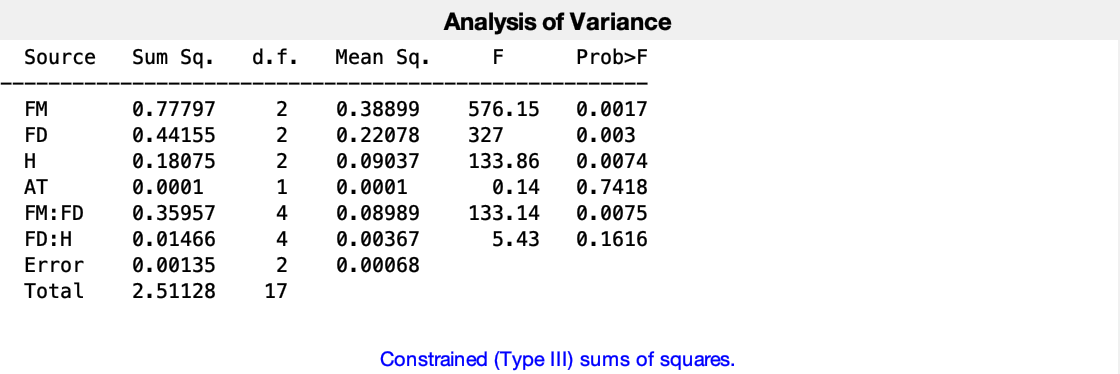

model_used=[1 0 0 0 ; 0 1 0 0 ; 0 0 1 0 ; 0 0 0 1; ... % Mains
           1 1 0 0 ; 0 1 1 0 ];

[p,tbl,stats] = anovan(L18{:,5},{L18{:,1},L18{:,2},L18{:,3},L18{:,4}},'varnames',{'FM','FD','H','AT'},'model',model_used);